# PCA-dimension-reduction based INP classification

load INP data

load('IndianPine_Data');%145*145*220
Img=double(IndianPine);
IndianPine=[];
save_dim=[1:103,110:149,164:220];
Img=Img(:,:,save_dim);%reserve only 200 bands to filter unnecessary noise
NbRow=145;
NbCol=145;
NbDim=200;
test_class=1:16;
GT = multibandread('92AV3GT_cls.bin',[145,145,1],'uint8',0,'bsq','n',{'Band','Direct',[1:1]});%training data source
% test_name=1:16;
dataname='INP';
factor_sum=[3,5,10,20,30,40,50];
% factor_sum = 5;
accur=0;

set parameters for kNN

options.K=1;% better preciseness with other odd parameter

reshape dimensions of Img into 2

for i=1:NbDim  
    Img_reduce_dimen(:,i)=reshape(Img(:,:,i),NbRow*NbCol,1);   
end

## imshow each of the first 5 bands

initialize sequence for PCA    

% Img_pca = pca_function(Img_reduce_dimen,5);
% Img_final = reshape(Img_pca,NbRow,NbCol,5);

display PCA result for each of the 5 bands

% for band=1:5
%     figure(band);
%     imshow(Img_final(:,:,band))
% end

## Assessment

10 iterations and set default prpotion--20% for training data

nrep=3;
Sampling=30;
for factor_serial=1:1
    Img_pca = pca_function(Img_reduce_dimen,factor_sum(factor_serial));
    Img_final = reshape(Img_pca,NbRow,NbCol,factor_sum(factor_serial));
    fprintf('current factor number : %d',factor_sum(factor_serial));
    for expt=1:nrep
        fprintf('\tprocessing on the experiment %d \n',expt);
        Train_row=[];Train_col=[];% Train_row and Train_col is the coordinates of training data
        Test_row=[];Test_col=[];% Test_row and Test_col is the coordinates of testing data
        Y_train=[];Y_test=[];% Y_train is the label of training data(N_train*1); Y_test is the label of testing data(N_test*1);
        X_train=[];X_test=[];% X_train is the training data(N_train*D); X_test is the testing data(N_test*D);
    
        %% 直接在GT中随机选择训练数据和测试数据
        for i=1:length(test_class)
            [row,col]=find(GT==test_class(i));%每一类地物所有像素点的行列坐标
            n(i)=length(row);%每一类地物包含像素点的数量
            temp=randperm(n(i));%随机打乱n(i)个数
            ind_train=temp(1:round(n(i)*Sampling/100));%第i类训练数据个数
            ind_test=temp(round(n(i)*Sampling/100)+1:end);%第i类测试数据个数
            Train_row=[Train_row;row(ind_train)];% 训练数据的row坐标
            Train_col=[Train_col;col(ind_train)];% 训练数据的row坐标
            n_train(i)=round(n(i)*Sampling/100);% 第i类训练数据的个数
            Test_row=[Test_row;row(ind_test)];% 测试数据的row坐标
            Test_col=[Test_col;col(ind_test)];% 测试数据的列坐标
            n_test(i)=n(i)- n_train(i);% 第i类测试数据的个数
        % 根据行列坐标提取train和test数据
            for j=1:n_train(i) 
                X_train=[X_train;reshape(Img_final(row(ind_train(j)),col(ind_train(j)),:),1,factor_sum(factor_serial))];
            end
        
            for j=1:n_test(i) 
                X_test=[X_test;reshape(Img_final(row(ind_test(j)),col(ind_test(j)),:),1,factor_sum(factor_serial))];
            end
        
            Y_train=[Y_train;repmat(test_class(i),n_train(i),1)];%训练数据的标签
            Y_test=[Y_test;repmat(test_class(i),n_test(i),1)];%测试数据的标签
        
        end
             result=My_KNN(X_train,Y_train,X_test,options.K);
             for i=1:length(X_test)
                 if(Y_test(i)==result(i))
                     accur=accur+1;
                 end
             end
             OA(expt)=accur/length(X_test);    %calculate OA(overall accuracy for each experiment)
             dis_OA=roundn(OA(expt),-3);    
             fprintf('\t   OA for current experiment is %d \n',dis_OA);
    end
end

current factor number : 3

	processing on the experiment 1 


	   OA for current experiment is 6.570000e-01 


	processing on the experiment 2 


	   OA for current experiment is 1.319000e+00 


	processing on the experiment 3 


	   OA for current experiment is 1.969000e+00 


calculate the average accurayc of the 3 experiments

%  OA_ave=mean(OA);
%  OA_std=sqrt(var(OA));

initialize sequence of kNN classification

for i=1:size(Img_final,1)  % for each row
   test_i_row=Img_final(i,:,:);%图像的第i行作为test数据进行分类
   test_i_row=reshape(test_i_row,size(Img_final,2),3);% size:N*D
   result_img(i,:)=My_KNN(X_train,Y_train,test_i_row,options.K);
 end

display the kNN-classified result of Img

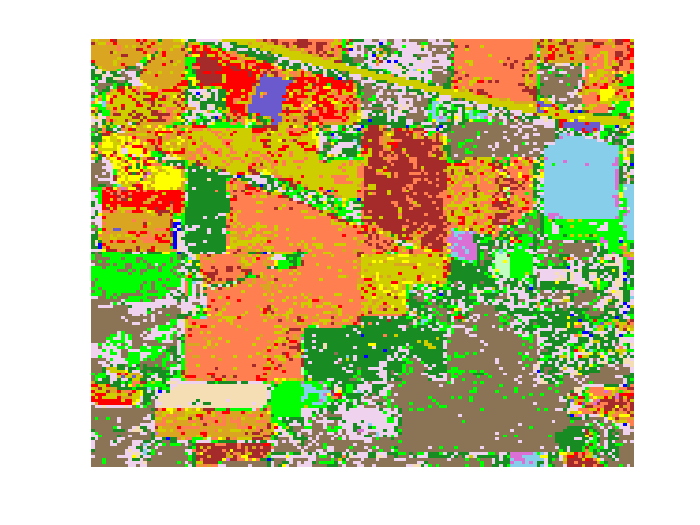

ColorTable=[218 112 214;% c1 Alfalfa(orchid) 
205 205 0; %c2 corn-notill (yellow 3) 
218 165 32; %c3 corn-min(dark goldenrod) 
255 255 0 ;%C4 corn(yellow) 
0,255,0; %c5 grass/pasture(green) 
24,139,34; %c6 grass/trees (forest green) 
193 255 193 ;%c7 grass/pasture-mowed (dark sea green1) 
135 206 235; %c8 hay-windrowed(sky blue) 
0 0 255;%c9 oats(blue) 
165 42 42; %c10 soybean-notill (brown) 
255 127 80; %c11 soybean-min(coral) 
255 0 0; %c12 soyebean-clean(red) 
245 222 179;%c13 wheat(wheat) 
139 115 85;%c14 woods(burlywood4) 
238 210 238;%c15blag-grass-tree-drives(thistle2) 
106 90 205;%c16 stone-steel towers (slate blue) 
];
ClassificationMap  = GenerateClassificationMap( size(Img_final,1), size(Img_final,2), ColorTable, reshape(result_img',size(Img_final,1)*size(Img_final,2),1));
figure;
image(ClassificationMap);  
axis off;